## Subsonic nozzle

h_g = linspace(2*10^6,25*10^6,100)

h_g = 	1.0e+07 *

    0.2000    0.2232    0.2465    0.2697    0.2929    0.3162    0.3394    0.3626    0.3859    0.4091    0.4323    0.4556    0.4788    0.5020    0.5253    0.5485    0.5717    0.5949    0.6182    0.6414    0.6646    0.6879    0.7111    0.7343    0.7576    0.7808    0.8040    0.8273    0.8505    0.8737    0.8970    0.9202    0.9434    0.9667    0.9899    1.0131    1.0364    1.0596    1.0828    1.1061    1.1293    1.1525    1.1758    1.1990    1.2222    1.2455    1.2687    1.2919    1.3152    1.3384


v_f = sqrt(2*h_g)

v_f = 	1.0e+03 *

    2.0000    2.1130    2.2202    2.3225    2.4205    2.5146    2.6054    2.6931    2.7780    2.8604    2.9405    3.0185    3.0945    3.1687    3.2411    3.3121    3.3815    3.4495    3.5162    3.5817    3.6459    3.7091    3.7712    3.8323    3.8925    3.9517    4.0101    4.0676    4.1243    4.1803    4.2355    4.2900    4.3438    4.3970    4.4495    4.5014    4.5527    4.6035    4.6537    4.7033    4.7525    4.8011    4.8492    4.8969    4.9441    4.9909    5.0372    5.0831    5.1286    5.1737


p_g = [9000; 15000; 20000]

p_g =         9000
       15000
       20000


density_f = (p_g./(v_f.^2))*1000

density_f =     2.2500    2.0158    1.8258    1.6685    1.5362    1.4233    1.3259    1.2409    1.1662    1.1000    1.0409    0.9878    0.9399    0.8964    0.8567    0.8204    0.7871    0.7564    0.7279    0.7016    0.6771    0.6542    0.6328    0.6128    0.5940    0.5763    0.5597    0.5440    0.5291    0.5150    0.5017    0.4890    0.4770    0.4655    0.4546    0.4442    0.4342    0.4247    0.4156    0.4068    0.3985    0.3904    0.3827    0.3753    0.3682    0.3613    0.3547    0.3483    0.3422    0.3362
    3.7500    3.3597    3.0430    2.7809    2.5603    2.3722    2.2098    2.0682    1.9437    1.8333    1.7348    1.6463    1.5665    1.4940    1.4279    1.3674    1.3118    1.2606    1.2132    1.1693    1.1284    1.0903    1.0547    1.0213    0.9900    0.9605    0.9328    0.9066    0.8818    0.8584    0.8361    0.8150    0.7950    0.7759    0.7577    0.7403    0.7237    0.7078    0.6926    0.6781    0.6641    0.6507    0.6379    0.6255    0.6136    0.6022    0.5912    0.5805    0.5

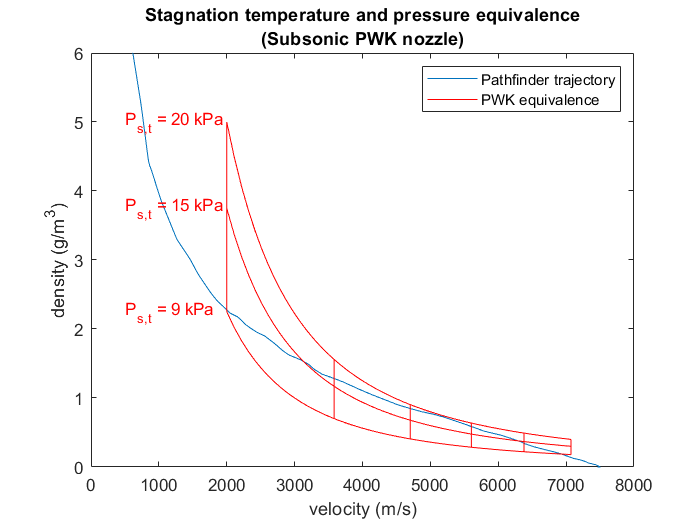



plot(velocity_interpolated,density_flight*1000)
xlabel("velocity (m/s)"); ylabel("density (g/m^3)")
hold on
plot(v_f,density_f, 'r')
hold on
for i = 1:length(v_f)
    if rem(i,20) == 0
        plot(ones(1,3)*v_f(:,i),density_f(:,i),'r')
        %text(v_f(i),density_f(3,i),"H_s_,_t = " + num2str(round(h_g(i),2,"significant")/1000000)+" MJ",'color','r')
    elseif i == 1
        plot(ones(1,3)*v_f(:,i),density_f(:,i),'r')
        %text(v_f(i),density_f(3,i),"H_s_,_t = " + num2str(round(h_g(i),1)/1000000)+" MJ",'color','r')
    end
    
    if rem(i,30) == 0
        
  %  elseif
        
    end
end


legend("Pathfinder trajectory","PWK equivalence")
hold on 
for i = 1:length(p_g)
    text(v_f(1)-1500,density_f(i,1),"P_s_,_t = " + num2str(p_g(i)/1000)+" kPa",'color','r')
    hold on
end
title({"Stagnation temperature and pressure equivalence","(Subsonic PWK nozzle)"})
ylim([0, 6])


d_co2 = 0.33*10^(-9)

d_co2 = 3.3000e-10

R_co2 =  8.31446261815324/44.01*1000

R_co2 = 188.9221

B = 1.380649*10^(-23)

B = 1.3806e-23

L = 1.325;
T = 183;
PT = 9353

PT = 9353

Kn = B*T/(sqrt(2)*(d_co2^2)*PT*L)

Kn = 1.3238e-06


72.3/0.00773

ans = 9.3532e+03